p.gravity = 9.81;       % [m/s^2] constant of gravity
p.al = 20/180*pi;       %[degree-->rad] grade angle
p.mass = 400 ;          %[kg] chassis mass
p.theta = 1.2;          %[kgm^2] inertia of wheel
p.r = 0.3;              %[m] wheel radius

% set payload & compute actual wheel load
fzN = 3100;
fz = p.mass*p.gravity*cos(p.al);

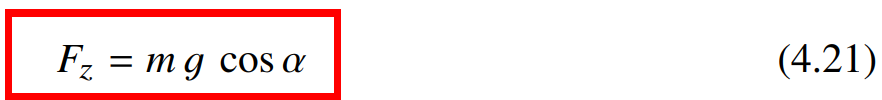

% long. tyre characteristic whith linear wheel load influence
p.dfx0 = 100000*fz/fzN;   % [N/-] initial incl. long. force char
p.fxm = 3200*fz/fzN;      % [N] maximum long. force
p.sxm = 0.1;              % [-] sx @ fx=fxm
p.fxs = 3000*fz/fzN;      % [N] long. sliding force
p.sxs = 0.8;              % [-] sx @ fx = fxs
p.cx = 160000;            % [N/m] long. tyre stifness
p.dx = 500;               % [N/(m/s)] long. tyre damping 
p.vN = 0.01;              % [m/s] fictitious velocity

% appropriate "damping" constant for enhanced braking torque model 
p.dN = p.r * sqrt(p.cx*p.theta);

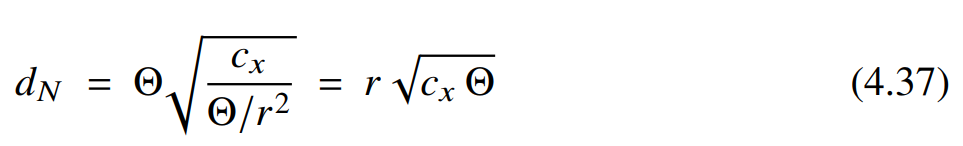

% set driving torque (time [s] , torque [Nm])
p.t_Drive       = [0.0   0.9   1.1   3.9   4.1   20.0];
p.Drive_Torque  = [0.0   0.0   1.0   1.0   0.0   0.0]*p.fxm*p.r;
% set braking torque (time [s] , torque [Nm])
p.t_Brake       = [0.0   5.95   6.05   17.95   18.05   20.0];
p.Brake_Torque  = [0.0   0.00   1.50   1.50   0.00   0.0]*p.fxm*p.r;
% perform simulation 
tE = min(max(p.t_Drive) , max(p.t_Brake)); % duration 

final time *t*E   

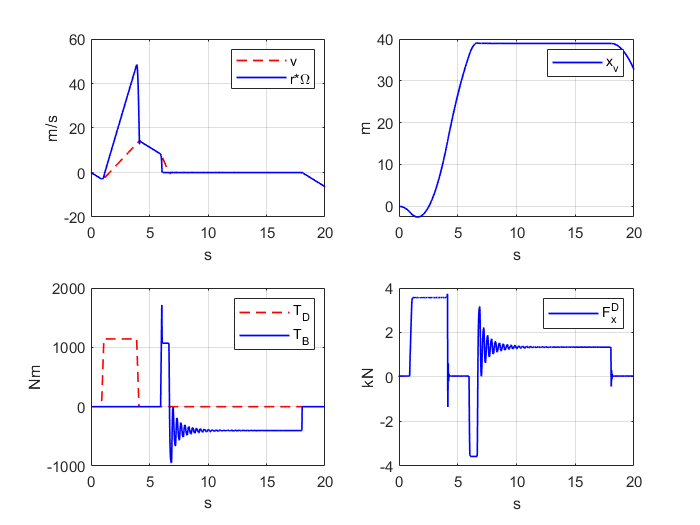

x0 = [ 0 ; 0 ; 0 ; 0 ]; % simple initial states 
[ tout , xout ] = ode23(@(t,x) fun_04_chassis_wheel_tire(t,x,p) , [0 , tE] , x0);
% get additional output quantities
sxi = tout;   fxi = tout;   tqb = tout;   tqd = tout;
for i=1 : length(tout)
    [xp , out] = fun_04_chassis_wheel_tire (tout(i),xout(i,:).',p);
    sxi (i) = out.sx;  fxi (i) = out.fxd;  tqb (i) = out.tq_B;  tqd (i) = out.tq_D; 
end
% plot results 
subplot(2,2,1) , plot(tout,xout(:,1),'--r','linewidth',1), hold on
plot(tout , p.r*xout(:,2),'b','linewidth',1) , grid on
xlabel('s') , ylabel('m/s') , legend('v','r*\Omega')
subplot(2,2,2) , plot(tout ,xout(:,4) , 'b' ,'LineWidth',1) , grid on
xlabel('s') , ylabel('m') , legend('x_v')
subplot(2,2,3) , plot(tout ,tqd , '--r' , 'LineWidth',1) , hold on
plot(tout , tqb , 'b' , 'LineWidth',1) , grid on
xlabel('s') , ylabel('Nm') , legend('T_D' , 'T_B')
subplot(2,2,4) , plot(tout , fxi/1000 , 'b' , 'LineWidth',1) , grid on
xlabel('s') , ylabel('kN') , legend('F_x^D')